# Honours Live Script 8

## Load Data

if ~exist("workspaceVarHonours", 'var')
    load matlabHonours.mat
    setInterpLatex()
end

## Save Data

if exist("workspaceVarHonours", 'var')
    clearVarsArray = clearVars();
    clear(clearVarsArray{:})
    clear clearVarsArray
    save matlabHonours.mat
end 

% set the default intepreter to latex
setInterpLatex()

## Contents

Rezoning - Townsville Section

Rezoning - North Section

Initial Conditions Setting

Effect of MPA Establishment

Final Experiment Initialisation

Study Area Figure

Effect of Correlation Figure

MPA Survival Probabilities

## Assumptions Made

% one thing which is probably important to note, is that the population
% counts for the initial conditions are significntaly lower here HOWEVER as
% I have just realised this is kinda dumb - the old ICs I was looking at
% accounted for the entire reef

% fuck idea - let's look at a comparison between population counts when the
% entire population is run, vs just a section - if there are big
% differences, it might be worthwhile rethinking how we are running these
% models

% something to consider that I realised was that the succession
% probabilities that I initially chose were then updated to the 0.94 which
% appears in my thesis

## Rezoning - Townsville Section

% let's now look Townsville - first set the border, then plot it
var1 = [147.25, 149.5];
var2 = [-20, -18.5];
borderTowns = [var1(1), var2(1); var1(2), var2(1); var1(2), var2(2); ...
    var1(1), var2(2); var1(1), var2(1)];

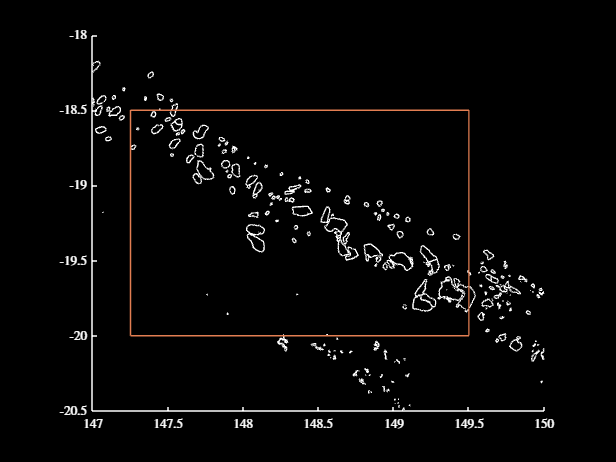

% plot shit
figure
var1 = [147, 150, -20.5, -18];
plotShapeStruct(GBRShapeCT, [], [], [], [], var1)
plot(borderTowns(:, 1), borderTowns(:, 2), '-', 'Color', getColour('o'))
darkFig()

% find the reefs that fit in with the above border
reefIndsTowns = zeros(nReefsCT, 1);
for i = 1:length(centroidsCT)

    % check if this fits into the border I have defined, along with a
    % minimum area tolerance for computational reasons
    c = centroidsCT(i, :);
    if c(1) > borderTowns(1, 1) && c(1) < borderTowns(2, 1) ...
            && c(2) > borderTowns(1, 2) && c(2) < borderTowns(3, 2) ...
            && areasCT(i) > 1.0456 * 10^-4
        reefIndsTowns(i) = 1;
    end

end
reefIndsTowns = reefIndsTowns > 0;
sum(reefIndsTowns)

ans = 100

% extract the relevant information
nReefsTowns = sum(reefIndsTowns);
conMatsTowns = conMatsCT;
for m = 1:nMatsCT
    conMatsTowns{m} = conMatsCT{m}(reefIndsTowns, reefIndsTowns);
end
areasTowns = areasCT(reefIndsTowns);
GBRShapeTowns = GBRShapeCT(reefIndsTowns);
centroidsTowns = centroidsCT(reefIndsTowns, :);

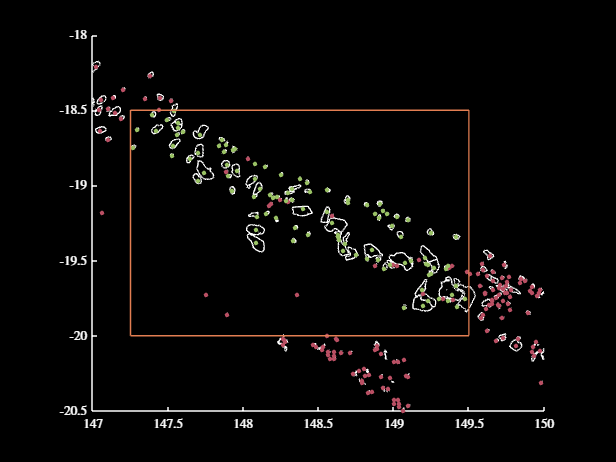

% plot the results again
figure
var1 = [147, 150, -20.5, -18];
plotShapeStruct(GBRShapeCT, [], [], [], [], var1)
plot(centroidsCT(~reefIndsTowns, 1), centroidsCT(~reefIndsTowns, 2), ...
    '.', 'Color', getColour('r'), 'MarkerSize', 10)
plot(centroidsCT(reefIndsTowns, 1), centroidsCT(reefIndsTowns, 2), ...
    '.', 'Color', getColour('g'), 'MarkerSize', 10)
plot(borderTowns(:, 1), borderTowns(:, 2), '-', 'Color', getColour('o'))
darkFig()

## Rezoning - North Section

% let's now look at the north GBR - first set the border, then plot it
var1 = [143.4, 144.55];
var2 = [-14.4, -13];
borderNorth = [var1(1), var2(1); var1(2), var2(1); var1(2), var2(2); ...
    var1(1), var2(2); var1(1), var2(1)];

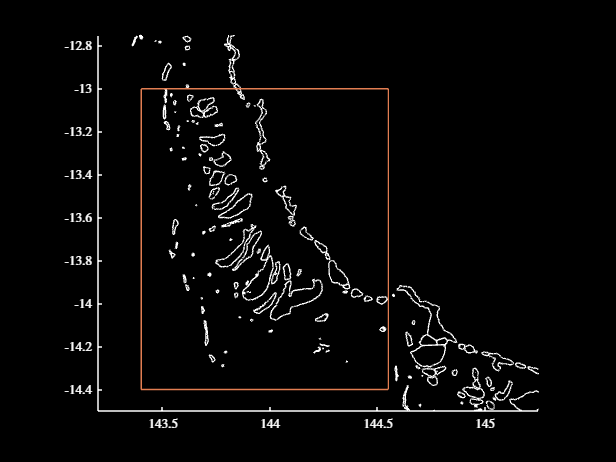

% plot shit
figure
var1 = [143.2, 145.25, -14.5, -12.75];
plotShapeStruct(GBRShapeCT, [], [], [], [], var1)
plot(borderNorth(:, 1), borderNorth(:, 2), '-', 'Color', getColour('o'))
darkFig()

% find the reefs that fit in with the above border
reefIndsNorth = zeros(nReefsCT, 1);
for i = 1:length(centroidsCT)

    % check if this fits into the border I have defined, along with a
    % minimum area tolerance for computational reasons
    c = centroidsCT(i, :);
    if c(1) > borderNorth(1, 1) && c(1) < borderNorth(2, 1) ...
            && c(2) > borderNorth(1, 2) && c(2) < borderNorth(3, 2)
        reefIndsNorth(i) = 1;
    end

end
reefIndsNorth = reefIndsNorth > 0;
sum(reefIndsNorth)

ans = 100

% extract the relevant information
nReefsTowns = sum(reefIndsNorth);
conMatsNorth = conMatsCT;
for m = 1:nMatsCT
    conMatsNorth{m} = conMatsCT{m}(reefIndsNorth, reefIndsNorth);
end
areasNorth = areasCT(reefIndsNorth);
GBRShapeNorth = GBRShapeCT(reefIndsNorth);
centroidsNorth = centroidsCT(reefIndsNorth, :);

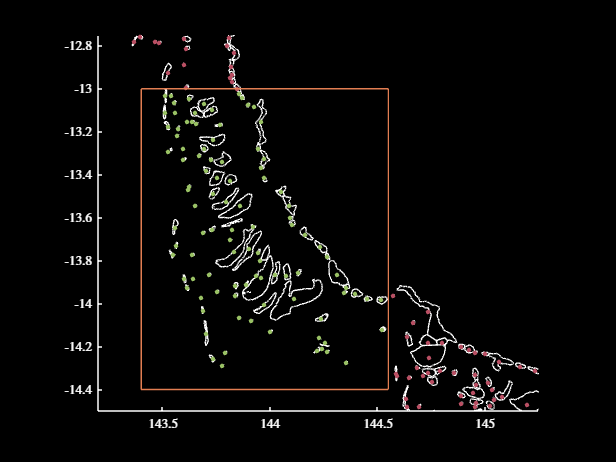

% plot the results again
figure
var1 = [143.2, 145.25, -14.5, -12.75];
plotShapeStruct(GBRShapeCT, [], [], [], [], var1)
plot(centroidsCT(~reefIndsNorth, 1), centroidsCT(~reefIndsNorth, 2), ...
    '.', 'Color', getColour('r'), 'MarkerSize', 10)
plot(centroidsCT(reefIndsNorth, 1), centroidsCT(reefIndsNorth, 2), ...
    '.', 'Color', getColour('g'), 'MarkerSize', 10)
plot(borderNorth(:, 1), borderNorth(:, 2), '-', 'Color', getColour('o'))
darkFig()

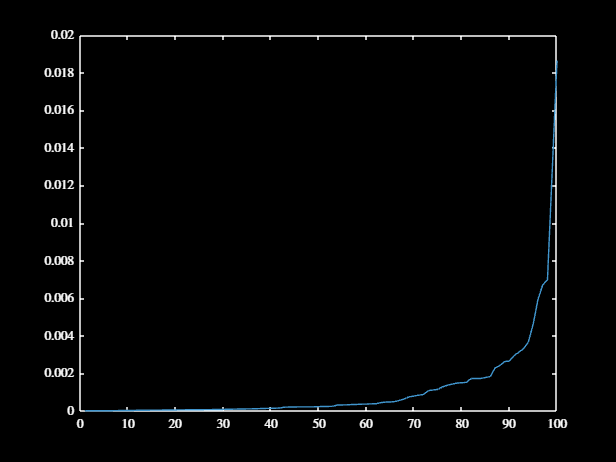

% quickly look at the distribution of areas
figure
plot(sort(areasNorth))
darkFig()

## Initial Conditions Setting

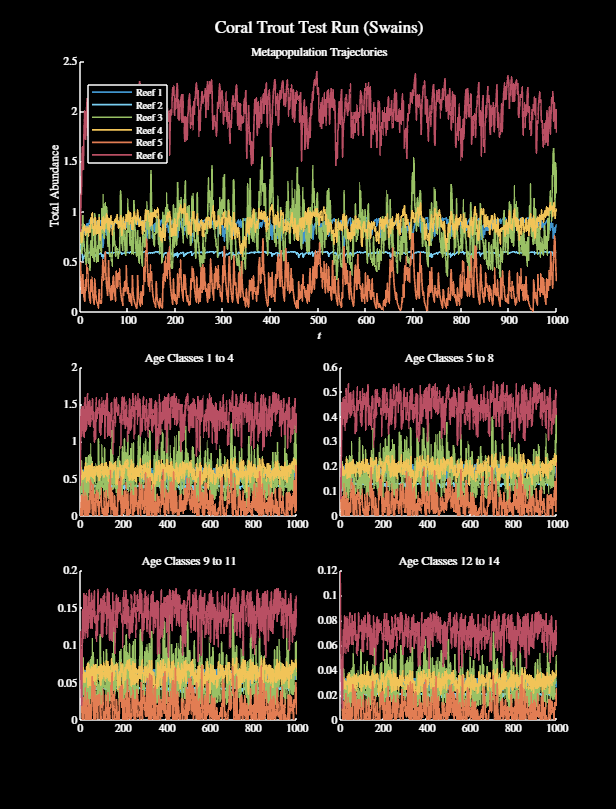

% first, let's look at the ICs for the Swains because why not
rng(113)
tWarmup = 1000;
successVecCT = [0.6, 0.7, 0.79, 0.79 * ones(1, 10)];
specStructCT.successVec = successVecCT;
randStruct.randType = "sequence";
randStruct.sequence = randi(length(conMatsSwains), 1, tWarmup - 1);
popInitTest = 0.05 * ones(length(conMatsSwains{1}), 14);
popMatTest = baseMetapopModel(conMatsSwains, areasSwains, ...
        popInitTest, tWarmup, specStructCT, randStruct);

% visualise some of the population trajectories
% visualise a random selection of the reefs
var1 = [1, 4, 5, 6, 78, 30];
tL = visualiseMetapop(popMatTest(var1, :, :), 1:tWarmup);
title(tL, "Coral Trout Test Run (Swains)", 'Interpreter', 'Latex')
darkFig()
figResize(1.75)


% either way this is fine, so let's call that the initial population
popInitSwains = mean(popMatTest(:, :, 900:1000), 3);

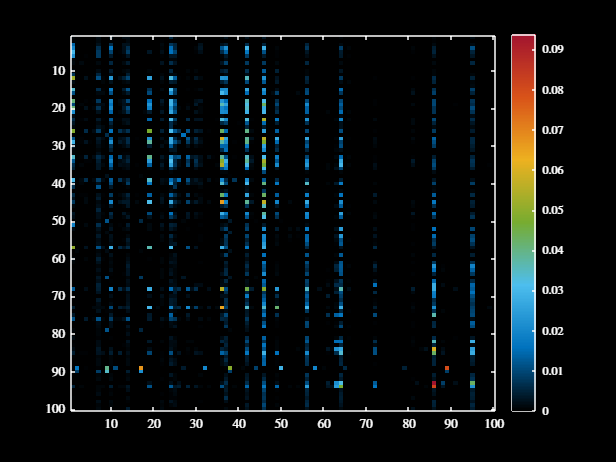

% hmmm, it appears possible that there is too little connectivity in this
% region to actually support a metapopulation
figure
i = 15;
imagesc(conMatsSwains{i})
colormap(myColourMap())
colorbar
darkFig()


% this kind of explains it - there is weirdly quite little connectivity
% between these reefs - may need to consider this in my analysis

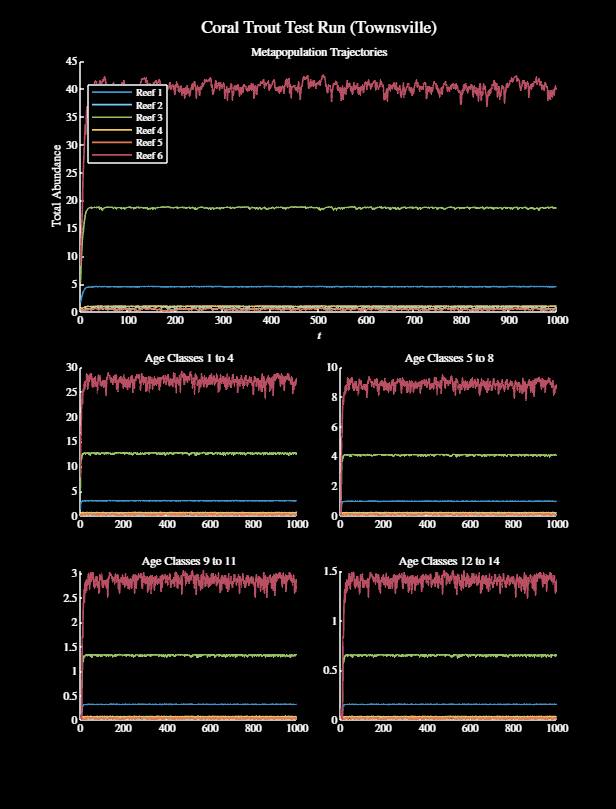

% let's now setup the initial conditions for Townsville
rng(136)
tWarmup = 1000;
randStruct.randType = "sequence";
randStruct.sequence = randi(length(conMatsTowns), 1, tWarmup - 1);
popInitTest = 0.05 * ones(length(conMatsTowns{1}), 14);
popMatTest = baseMetapopModel(conMatsTowns, areasTowns, ...
        popInitTest, tWarmup, specStructCT, randStruct);

% visualise some of the population trajectories
var1 = randi(nReefsTowns, 1, 6);
tL = visualiseMetapop(popMatTest(var1, :, :), 1:tWarmup);
title(tL, "Coral Trout Test Run (Townsville)", 'Interpreter', 'Latex')
darkFig()
figResize(1.75)


% let's call that the initial population
popInitTowns = mean(popMatTest(:, :, 900:1000), 3);

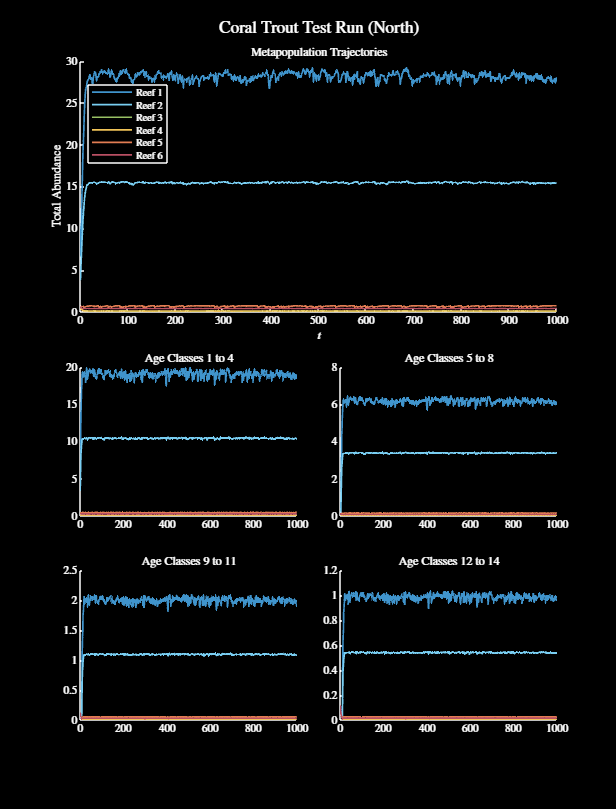

% finally, let's set up the ICs for the north region
rng(136)
tWarmup = 1000;
randStruct.randType = "sequence";
randStruct.sequence = randi(length(conMatsNorth), 1, tWarmup - 1);
popInitTest = 0.05 * ones(length(conMatsNorth{1}), 14);
popMatTest = baseMetapopModel(conMatsNorth, areasNorth, ...
        popInitTest, tWarmup, specStructCT, randStruct);

% visualise some of the population trajectories
nReefsNorth = sum(reefIndsNorth);
var1 = randi(nReefsNorth, 1, 6);
tL = visualiseMetapop(popMatTest(var1, :, :), 1:tWarmup);
title(tL, "Coral Trout Test Run (North)", 'Interpreter', 'Latex')
darkFig()
figResize(1.75)


% let's call that the initial population
popInitNorth = mean(popMatTest(:, :, 900:1000), 3);

% also, for reasons involving the MPA code below, also establish an initial
% population thing for the entire GBR
rng(191)
tWarmup = 1000;
randStruct.randType = "sequence";
randStruct.sequence = randi(length(conMatsCT), 1, tWarmup - 1);
popInitTest = 0.05 * ones(length(conMatsCT{1}), 14);
popMatTest = baseMetapopModel(conMatsCT, areasCT, ...
        popInitTest, tWarmup, specStructCT, randStruct);

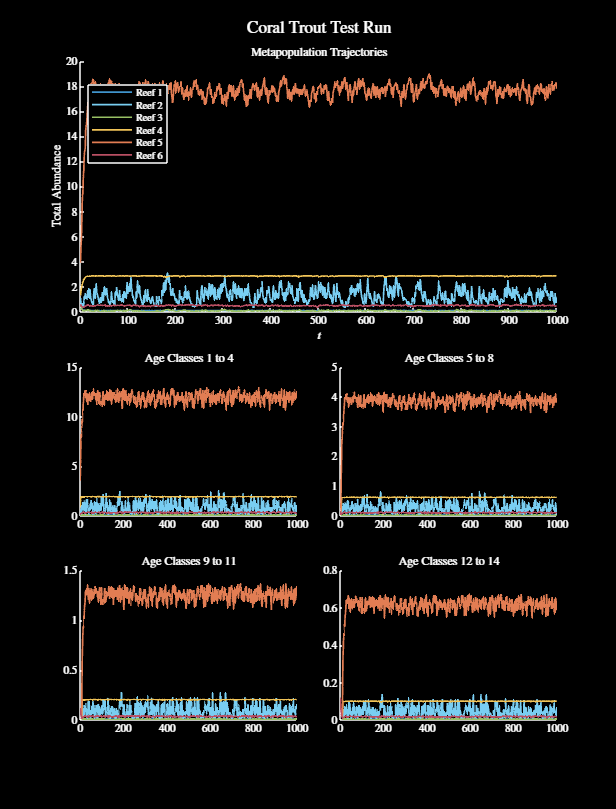

% visualise some of the population trajectories
nReefsCT = length(conMatsCT{1});
var1 = randi(nReefsCT, 1, 6);
tL = visualiseMetapop(popMatTest(var1, :, :), 1:tWarmup);
title(tL, "Coral Trout Test Run", 'Interpreter', 'Latex')
darkFig()
figResize(1.75)


% let's call that the initial population
popInitCT = mean(popMatTest(:, :, 900:1000), 3);

% one thing which would be a good idea, is to make sure that not too many
% of the reefs begin with a zero population, just as a bit of a sanity
% check and test before I go off and gather shitloads of data
figure
hold on
var1 = mean(popInitSwains, 2);
sum(var1 == 0)

ans = 0

plot(sort(var1))
var1 = mean(popInitTowns, 2);
sum(var1 == 0)

ans = 1

plot(sort(var1))
var1 = mean(popInitNorth, 2);
sum(var1 == 0)

ans = 0

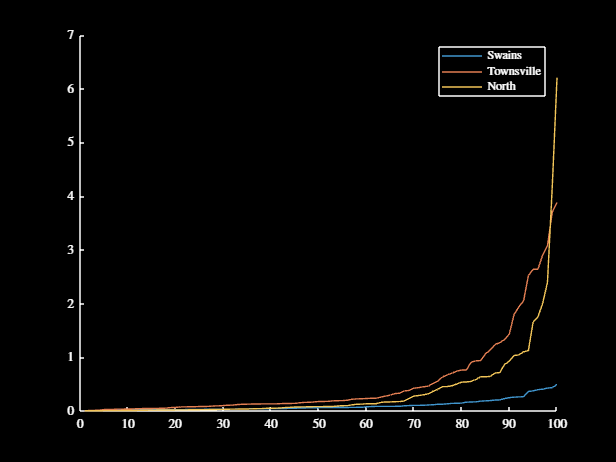

plot(sort(var1))
legend("Swains", "Townsville", "North")
darkFig()

## Effect of MPA Establishment

% I REDID THIS LATER OK IT'S LAST IN THIS LIVE SCRIPT

% want to look at the effects of establishing an MPA on a single reef at a
% time, so I can visualise the type of improvement we're getting
rng(191)
var1 = [891, 4, 5, 78, 30];
tMax = 50;
successVecCT = [0.6, 0.7, 0.79, 0.79 * ones(1, 10)]

successVecCT =     0.6000    0.7000    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900


specStructCT.successVec = successVecCT;
successVecCTMPA = [0.68, 0.83, 0.95, 0.97 * ones(1, 10)]

successVecCTMPA =     0.6800    0.8300    0.9500    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700


randStruct.randType = "sequence";
randStruct.sequence = randi(length(conMatsCT), 1, tMax - 1);
actionStruct.type = "MPA";
actionVec = zeros(1, length(conMatsCT{1}));
actionStruct.actionVec = actionVec;
actionStruct.actionEffect = successVecCTMPA;
popInitTest = 50 * ones(length(conMatsCT{1}), 14);
actionStruct.type = "MPA";

% run without the MPA
popMatTest1 = baseMetapopModel(conMatsCT, areasCT, ...
        popInitCT, tMax, specStructCT, randStruct);

% to avoid any interactions between the reefs, let's set up a popMatTest2
% here and kinda only update the rows corresponding to the single MPA
% chosen each time fuck this is a long comment but I'm sure you will see
% what I mean
popMatTest2 = popMatTest1;
for r = 1:length(var1)
    
    % run with the MPA
    actionVec = zeros(1, nReefsCT);
    actionVec(var1(r)) = 1;
    actionStruct.actionVec = actionVec;
    var2 = baseMetapopModel(conMatsCT, areasCT, popInitCT, tMax, ...
        specStructCT, randStruct, actionStruct);
    popMatTest2(var1(r), :, :) = var2(var1(r), :, :);

end

% convert the results to biomasses
biomassMat1 = convertAgeClasses(popMatTest1, massVecCT);
biomassMat2 = convertAgeClasses(popMatTest2, massVecCT);

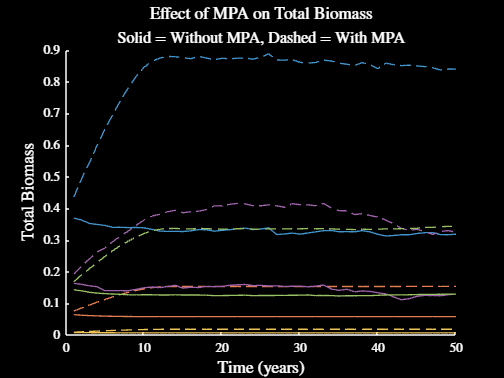

% plot the results
figure
hold on
for r = 1:length(var1)
    plot(biomassMat1(var1(r), :), 'Color', getColour(r), 'LineWidth', 1)
    plot(biomassMat2(var1(r), :), '--', 'Color', getColour(r), ...
        'LineWidth', 1)
end
var2 = 13;
xlabel("Time (years)", "FontSize", var2)
ylabel("Total Biomass", "FontSize", var2)
title("Effect of MPA on Total Biomass", "FontSize", var2)
subtitle("Solid = Without MPA, Dashed = With MPA", "FontSize", 0.9 * var2)

% save both a light mode version of the figure, and a dark mode version of
% the figure
% saveFig("effectOfMPAPresence")
darkFig()

% saveFig("effectOfMPAPresenceDM")

## Study Area Figure

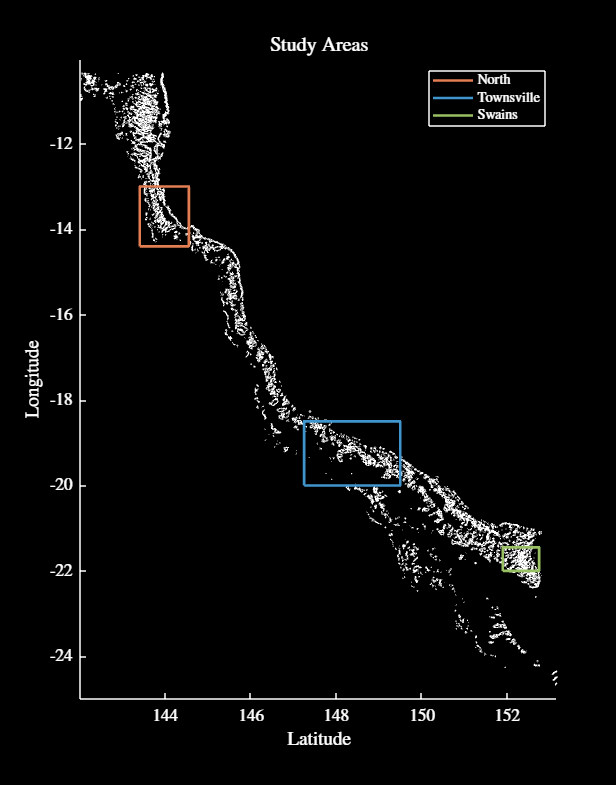

% plot that shi
var1 = 16;
figure
hold on
figResize(1.7)
plot(borderNorth(:, 1), borderNorth(:, 2), '-', 'Color', getColour('o'), ...
    'LineWidth', 2)
plot(borderTowns(:, 1), borderTowns(:, 2), '-', 'Color', getColour('b'), ...
    'LineWidth', 2)
plot(borderSwains(:, 1), borderSwains(:, 2), '-', 'Color', getColour('g'), ...
    'LineWidth', 2)
plotShapeStruct(GBRShapeLL)
plot(borderNorth(:, 1), borderNorth(:, 2), '-', 'Color', getColour('o'), ...
    'LineWidth', 2)
plot(borderTowns(:, 1), borderTowns(:, 2), '-', 'Color', getColour('b'), ...
    'LineWidth', 2)
plot(borderSwains(:, 1), borderSwains(:, 2), '-', 'Color', getColour('g'), ...
    'LineWidth', 2)
title("Study Areas")
xlabel("Latitude")
ylabel("Longitude")
legend("North", "Townsville", "Swains")
setFontSize(14)

% save dat shit
saveFig("studyAreas.png")
darkFig()
saveFig("studyAreasDM.png")

% look at connection distances lmao
centroidsDist = pdistLatLon(centroidsCT);

% identify connections with a decent number of nonzero elements
var1 = [];
for i = 1:nReefsCT
    for j = 1:nReefsCT
        var2 = 0;
        for t = 1:length(conMatsCT)
            var2 = var2 + (conMatsCT{t}(i, j) > 0);
        end
        if var2 > 0.5 * length(conMatsCT)
            var1 = [var1, centroidsDist(i, j)];
        end
    end
end
max(var1)

ans = 915.1124

## Effect of Correlation Figure

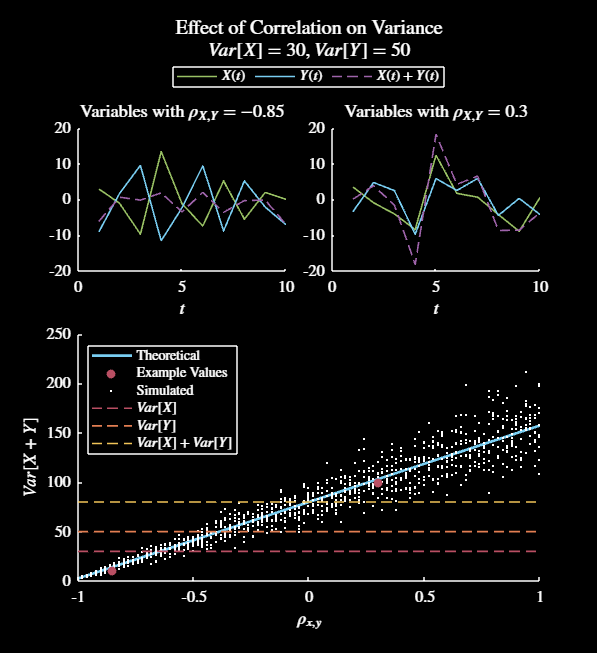

% think about maybe backing this up with some time series generated with
% specific covariances
rng(4)
varX = 30;
varY = 50;
corrVec = linspace(-1, 1, 101);
totalVar = varX + varY + 2 * sqrt(varX) * sqrt(varY) * corrVec;

% generate some sets of random variables with varying levels of correlation
totalVarSim = zeros(10, length(corrVec));
for i = 1:length(corrVec)
    for j = 1:size(totalVarSim, 1)

        % setup the correct covariance matrix
        covMat = [varX, sqrt(varX) * sqrt(varY) * corrVec(i);
            sqrt(varX) * sqrt(varY) * corrVec(i), varY];

        % generate correlated random values
        mvnVecs = mvnrnd([0, 0], covMat, 100);

        % calculate and store the total variance
        totalVarSim(j, i) = var(sum(mvnVecs, 2));

    end
end

% plot the results
fS = 12;
figure
tL = tiledlayout(5, 2, "TileSpacing", "compact");

% create two extra time series, for illustrative purposes, and plot their
% time series
var1 = zeros(2, 2);
var1(1, 1) = -0.85;
covMat = [varX, sqrt(varX) * sqrt(varY) * var1(1, 1);
    sqrt(varX) * sqrt(varY) * var1(1, 1), varY];
mvnVecs = mvnrnd([0, 0], covMat, 10);
var1(1, 2) = var(sum(mvnVecs, 2));

% plot the first time series thingy
lW = 1.2;
axVec = [];
axVec(1) = nexttile([2, 1]);
hold on
plot(mvnVecs(:, 1), 'Color', getColour('g'), 'LineWidth', lW)
plot(mvnVecs(:, 2), 'Color', getColour('lb'), 'LineWidth', lW)
plot(mvnVecs(:, 1) + mvnVecs(:, 2), '--', 'Color', getColour('p'), ...
    'LineWidth', lW)
title("Variables with $\rho_{X, Y} = " + num2str(var1(1, 1)) + "$")
var8 = legend("$X(t)$", "$Y(t)$", "$X(t) + Y(t)$", 'Location', ...
    'layout', 'Orientation', 'horizontal');
var8.Layout.Tile = "North";
xlabel("$t$")

% generate the second time series thingy
var1(2, 1) = 0.3;
covMat = [varX, sqrt(varX) * sqrt(varY) * var1(2, 1);
    sqrt(varX) * sqrt(varY) * var1(2, 1), varY];
mvnVecs = mvnrnd([0, 0], covMat, 10);
var1(2, 2) = var(sum(mvnVecs, 2));

% plot the second time series thingy
axVec(2) = nexttile([2, 1]);
hold on
plot(mvnVecs(:, 1), 'Color', getColour('g'), 'LineWidth', lW)
plot(mvnVecs(:, 2), 'Color', getColour('lb'), 'LineWidth', lW)
plot(mvnVecs(:, 1) + mvnVecs(:, 2), '--', 'Color', getColour('p'), ...
    'LineWidth', lW)
title("Variables with $\rho_{X, Y} = " + num2str(var1(2, 1)) + "$")
xlabel("$t$")
linkaxes(axVec)

% plot the general relationship
nexttile([3, 2])
hold on
plot(corrVec, totalVar, 'LineWidth', 2, 'Color', getColour('lb'))
yline(varX, '--', 'Color', getColour('r'), 'Alpha', 1, 'LineWidth', lW)
yline(varY, '--', 'Color', getColour('o'), 'Alpha', 1, 'LineWidth', lW)
yline(varX + varY, '--', 'Color', getColour('y'), 'Alpha', 1, ...
    'LineWidth', lW)
plot(var1(:, 1), var1(:, 2), '.', 'Color', getColour('r'), ...
    'MarkerSize', 20)
plot(corrVec, totalVarSim, 'k.', 'MarkerSize', 5)
plot(var1(:, 1), var1(:, 2), '.', 'Color', getColour('r'), ...
    'MarkerSize', 20)
title(tL, "Effect of Correlation on Variance", 'FontSize', ...
    'Interpreter', 'latex')
subtitle(tL, "$Var[X] = " + num2str(varX) + ", \, Var[Y] = " ...
    + num2str(varY) + "$", 'Interpreter', 'latex')
xlabel("$\rho_{x, y}$")
ylabel("$Var[ X + Y ]$")
legend("Theoretical", "$Var[X]$", "$Var[Y]$", "$Var[X] + Var[Y]$",  ...
    "Example Values", "Simulated", 'Location', 'northwest')
figResize(1.75, 1.2)
setFontSize(13)

% save the output
saveFig("corrExample")
darkFig()
saveFig("corrExampleDM")

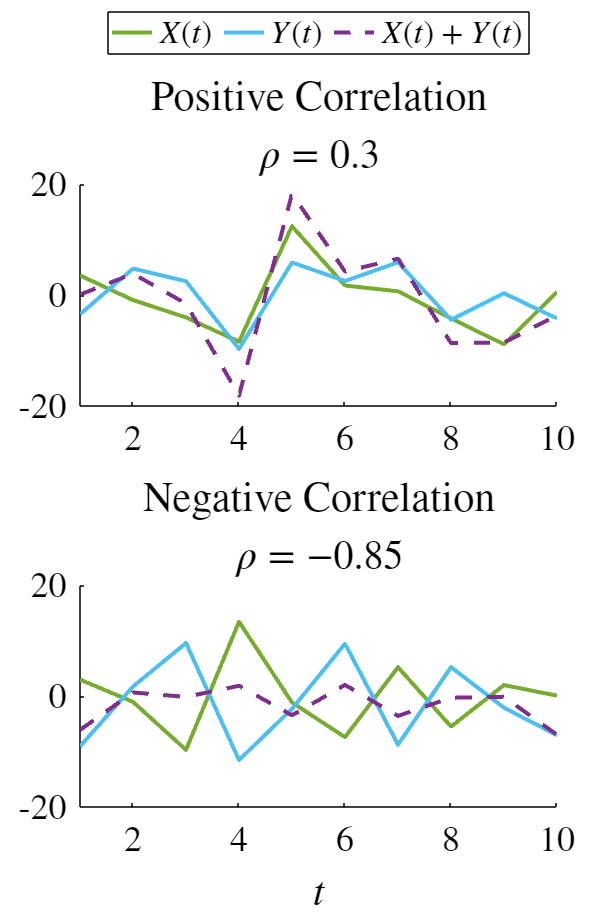

% also make a figure for the presentation of the first two panels only
rng(4)

varX = 30;
varY = 50;
corrVec = linspace(-1, 1, 101);
totalVar = varX + varY + 2 * sqrt(varX) * sqrt(varY) * corrVec;

% generate some sets of random variables with varying levels of correlation
totalVarSim = zeros(10, length(corrVec));
for i = 1:length(corrVec)
    for j = 1:size(totalVarSim, 1)

        % setup the correct covariance matrix
        covMat = [varX, sqrt(varX) * sqrt(varY) * corrVec(i);
            sqrt(varX) * sqrt(varY) * corrVec(i), varY];

        % generate correlated random values
        mvnVecs = mvnrnd([0, 0], covMat, 100);

        % calculate and store the total variance
        totalVarSim(j, i) = var(sum(mvnVecs, 2));

    end
end

figure
tL = tiledlayout(2, 1, "TileSpacing", "compact");

% create two extra time series, for illustrative purposes, and plot their
% time series
var1 = zeros(2, 2);
var1(1, 1) = -0.85;
covMat = [varX, sqrt(varX) * sqrt(varY) * var1(1, 1);
    sqrt(varX) * sqrt(varY) * var1(1, 1), varY];
mvnVecs1 = mvnrnd([0, 0], covMat, 10);
var1(1, 2) = var(sum(mvnVecs1, 2));

% generate the second time series thingy
var1(2, 1) = 0.3;
covMat = [varX, sqrt(varX) * sqrt(varY) * var1(2, 1);
    sqrt(varX) * sqrt(varY) * var1(2, 1), varY];
mvnVecs2 = mvnrnd([0, 0], covMat, 10);
var1(2, 2) = var(sum(mvnVecs2, 2));

% plot the second time series thingy
axVec = [];
axVec(1) = nexttile;
hold on
lW = 3;
plot(mvnVecs2(:, 1), 'Color', getColour('g'), 'LineWidth', lW)
plot(mvnVecs2(:, 2), 'Color', getColour('lb'), 'LineWidth', lW)
plot(mvnVecs2(:, 1) + mvnVecs2(:, 2), '--', 'Color', getColour('p'), ...
    'LineWidth', lW)
var8 = legend("$X(t)$", "$Y(t)$", "$X(t) + Y(t)$", 'Location', ...
    'layout', 'Orientation', 'horizontal');
var8.Layout.Tile = "North";
title("Positive Correlation") 
subtitle("$\rho = " + num2str(var1(2, 1)) + "$")

% plot the first time series thingy
axVec(2) = nexttile;
hold on
plot(mvnVecs1(:, 1), 'Color', getColour('g'), 'LineWidth', lW)
plot(mvnVecs1(:, 2), 'Color', getColour('lb'), 'LineWidth', lW)
plot(mvnVecs1(:, 1) + mvnVecs1(:, 2), '--', 'Color', getColour('p'), ...
    'LineWidth', lW)
title("Negative Correlation")
subtitle("$\rho = " + num2str(var1(1, 1)) + "$")
xlabel(tL, "$t$", 'Interpreter', 'latex')
linkaxes(axVec)
figResize(2)
setFontSize(30)
lightFig()
saveFig("corrExamplePP2")

## Final Experiment Initialisation

% start with generating the sequences of random numbers corresponding to
% the sequences of connectivity matrices to be used in each simulation
rng(1)

% setup some key parameters
nSims = 100;
tWarmup = 20;
tObs = 20;
tMPA = 40;
warmupSeqs = cell(nSims, 1);
obsSeqs = cell(nSims, 1);
mpaSeqs = cell(nSims, 1);

% loop over each simulation, and generate some random matrices
for s = 1:nSims
    warmupSeqs{s} = randi(nMatsCT, tWarmup, 1);
    obsSeqs{s} = randi(nMatsCT, tObs, 1);
    mpaSeqs{s} = randi(nMatsCT, tMPA, 1);
end

% assign all these values to the simStruct
simStruct = struct();
simStruct.tWarmup = tWarmup;
simStruct.tObs = tObs;
simStruct.tMPA = tMPA;
simStruct.warmupSeqs = warmupSeqs;
simStruct.obsSeqs = obsSeqs;
simStruct.mpaSeqs = mpaSeqs;
simStruct.resources = 0.33;
simStructFin = simStruct

simStructFin = struct with fields:
       tWarmup: 20
          tObs: 20
          tMPA: 40
    warmupSeqs: {100×1 cell}
       obsSeqs: {100×1 cell}
       mpaSeqs: {100×1 cell}
     resources: 0.3300



% clear them to save workspace
clear tWarmup tObs tMPA warmupSeqs obsSeqs mpaSeqs nSims

% I think evetually these values need to be passed into randstruct

% note - from what I can gather, my code currently treats the IC as year 1,
% and so if you give the code 20 years max you really only simulate 19 -
% this is something I should definitely fix once I can be fucet

% going to save these rng sequences in a separate workspace just in case
save simStructWorkspace.mat simStruct 

% need to also form the areaStructs, and all the other structs too

% do the areaStruct for the Swains
areaStructSwains = struct();
areaStructSwains.areas = areasSwains;
areaStructSwains.conMats = conMatsSwains;
areaStructSwains.initPop = popInitSwains;

% do the areaStruct for the Townsville area
areaStructTowns = struct();
areaStructTowns.areas = areasTowns;
areaStructTowns.conMats = conMatsTowns;
areaStructTowns.initPop = popInitTowns;

% do the areaStruct for the North area
areaStructNorth = struct();
areaStructNorth.areas = areasNorth;
areaStructNorth.conMats = conMatsNorth;
areaStructNorth.initPop = popInitNorth;

% make sure that the randStruct and simStruct are set up correctly
randStructFin = struct();
randStructFin.randType = "sequence";
randStructFin.sequence = []

randStructFin = struct with fields:
    randType: "sequence"
    sequence: []


specStructCT

specStructCT = struct with fields:
         alpha: 1.5000e-05
          beta: 1.0000e-08
    successVec: [0.6000 0.7000 0.7900 0.7900 0.7900 0.7900 0.7900 0.7900 0.7900 0.7900 0.7900 0.7900 0.7900]
     fecundVec: [5.6556e+04 2.8326e+05 6.1196e+05 9.5337e+05 1.2570e+06 1.5049e+06 1.6972e+06 1.8415e+06 1.9476e+06 2.0244e+06 2.0796e+06 2.1189e+06 2.1468e+06 2.1665e+06]
    weightings: [0.1229 0.2092 0.2698 0.3123 0.3421 0.3631 0.3778 0.3881 0.3953 0.4004 0.4040 0.4065 0.4082 0.4095]
       massVec: [0.1229 0.2092 0.2698 0.3123 0.3421 0.3631 0.3778 0.3881 0.3953 0.4004 0.4040 0.4065 0.4082 0.4095]


actionStructFin = actionStructCT

actionStructFin = struct with fields:
            type: "MPA"
       actionVec: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
    actionEffect: [0.6000 0.7000 0.8300 0.9400 0.9400 0.9400 0.9400 0.9400 0.9400 0.9400 0.9400 0.9400 0.9400]


% need to also set up the method struct (will need to change it for each
% sim, but having a global variable to start from is useful)
methodStruct = struct();
methodStruct.methodInd = "MPTPop";
methodStruct.meanVarWeight = 1;
methodStruct.classWeights = specStructCT.weightings;

% change the specStruct weightings to massVec
specStructCT.massVec = specStructCT.weightings;

% change the action and species structures to to update with the new
% survival probabilities
successVecCT = [0.6, 0.7, 0.79, 0.79 * ones(1, 10)]

successVecCT =     0.6000    0.7000    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900


specStructCT.successVec = successVecCT;
successVecCTMPA = [0.68, 0.83, 0.95, 0.97 * ones(1, 10)]

successVecCTMPA =     0.6800    0.8300    0.9500    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700


actionStructFin.actionEffect = successVecCTMPA;

## MPA Survival Probabilities

% based on the data from Emslie et al. 2015, my previous probability
% choices for fish survival resulted in increases in biomass which weren't
% entirely useful - let's now look towards increasing them, once I've read
% Mike E's paper

% let's write a for loop which can calculate the expected biomass contribution
% produced from a single fish through it's entire lifecycle
massVecCT 

massVecCT =     0.1229    0.2092    0.2698    0.3123    0.3421    0.3631    0.3778    0.3881    0.3953    0.4004    0.4040    0.4065    0.4082    0.4095


successVecCT = [0.6, 0.7, 0.79, 0.79 * ones(1, 10)]

successVecCT =     0.6000    0.7000    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900    0.7900


specStructCT.successVec = successVecCT;
successVecCTMPA = [0.68, 0.83, 0.95, 0.97 * ones(1, 10)]

successVecCTMPA =     0.6800    0.8300    0.9500    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700    0.9700


expBiomassFunc = @(successVec) sum(1 * (massVecCT .* cumprod([1, successVec])))

expBiomassFunc = function_handle with value:
    @(successVec)sum(1*(massVecCT.*cumprod([1,successVec])))


expBiomassNormal = expBiomassFunc(successVecCT)

expBiomassNormal = 0.8902

expBiomassMPA = expBiomassFunc(successVecCTMPA)

expBiomassMPA = 2.3501

var1 = expBiomassMPA / expBiomassNormal

var1 = 2.6400


% redo the figure of change in reef biomass so that I can verify that this
% seems reasonable - really should do this for a large subset of reefs, to
% ensure that biomass on average will have increased by a certain amount -
% this will account for the positive feedback loop of self recruitment
% too, which is definitely something to be aware of

% as the good ol' paper says, should be aiming for 2.5 times increase in
% biomass

% let's do the above, based on the code I applied earlier
% want to look at the effects of establishing an MPA on a single reef at a
% time, so I can visualise the type of improvement we're getting
rng(191)
% reefInds = [891, 4, 5, 78, 30];
reefInds = randi(nReefsCT, 10, 1);
tMax = 50;
randStruct.randType = "sequence";
randStruct.sequence = randi(length(conMatsCT), 1, tMax - 1);
actionStruct.type = "MPA";
actionVec = zeros(1, length(conMatsCT{1}));
actionStruct.actionVec = actionVec;
actionStruct.actionEffect = successVecCTMPA;
popInitTest = 50 * ones(length(conMatsCT{1}), 14);
actionStruct.type = "MPA";

% run without the MPA
popMatTest1 = baseMetapopModel(conMatsCT, areasCT, ...
        popInitCT, tMax, specStructCT, randStruct);

% to avoid any interactions between the reefs, let's set up a popMatTest2
% here and kinda only update the rows corresponding to the single MPA
% chosen each time fuck this is a long comment but I'm sure you will see
% what I mean
popMatTest2 = popMatTest1;
for r = 1:length(reefInds)

    % run with the MPA
    actionVec = zeros(1, nReefsCT);
    actionVec(reefInds(r)) = 1;
    actionStruct.actionVec = actionVec;
    var2 = baseMetapopModel(conMatsCT, areasCT, popInitCT, tMax, ...
        specStructCT, randStruct, actionStruct);
    popMatTest2(reefInds(r), :, :) = var2(reefInds(r), :, :);

end

% convert the results to biomasses
biomassMat1 = convertAgeClasses(popMatTest1, massVecCT);
biomassMat2 = convertAgeClasses(popMatTest2, massVecCT);

% look at the ratios in changes of biomass
biomassRatios = sum(biomassMat2(reefInds, :), 2) ...
    ./ sum(biomassMat1(reefInds, :), 2)

biomassRatios =     2.5005
    2.5290
    2.4929
    2.4914
    2.4942
    2.5377
    2.4583
    2.5432
    2.4981
    2.5391


mean(biomassRatios)

ans = 2.5084

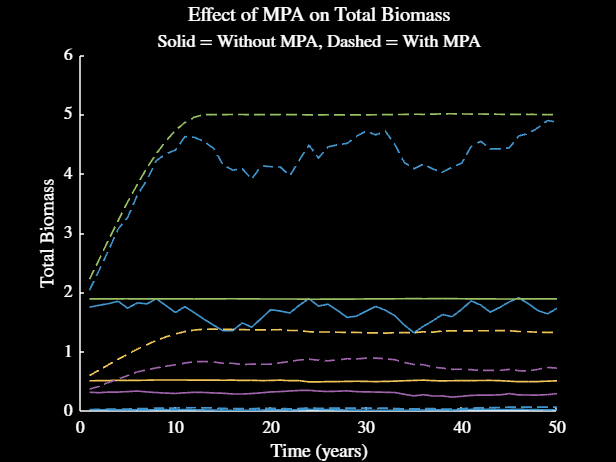

% plot the results
figure
hold on
for r = 1:2:length(reefInds)
    plot(biomassMat1(reefInds(r), :), 'Color', getColour(r), 'LineWidth', ...
        1.25)
    plot(biomassMat2(reefInds(r), :), '--', 'Color', getColour(r), ...
        'LineWidth', 1.25)
end
var2 = 13;
xlabel("Time (years)")
ylabel("Total Biomass")
title("Effect of MPA on Total Biomass")
subtitle("Solid = Without MPA, Dashed = With MPA")
setFontSize(14)

% save both a light mode version of the figure, and a dark mode version of
% the figure
saveFig("effectOfMPAPresence")
darkFig()
saveFig("effectOfMPAPresenceDM")